## **Loading the Data**

Useing the image datastore function to add the data and assign labels accordingly

%Loading the data set
% Clear workspace
clear; close all; clc;
% Images Datapath – Please modify your path accordingly
datapath='cell_images';

% Image Datastore
imds=imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13778
    Uninfected     13779


## Visualizing the Dataset

We visualize by randomly picking 20 images from the data set 

This data set has 2 main classes namely:

- Parasitized

- Uninfected

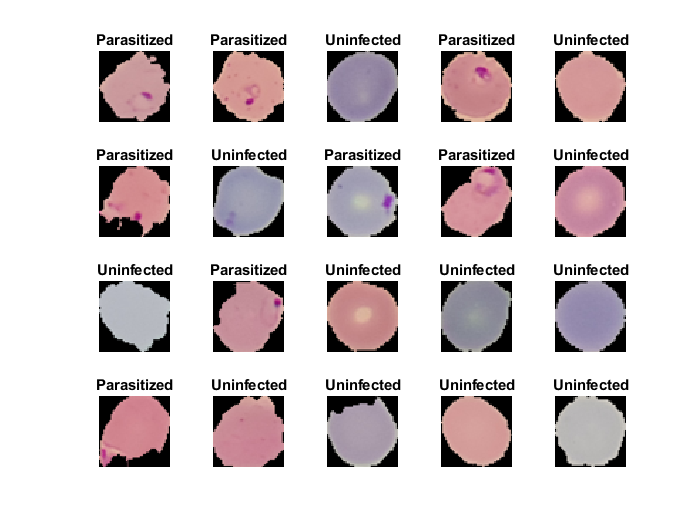

% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);
figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

## Applying the preprocessing function 

Applying the preprocessing function to a sample set of image to get an idea as to what is being done

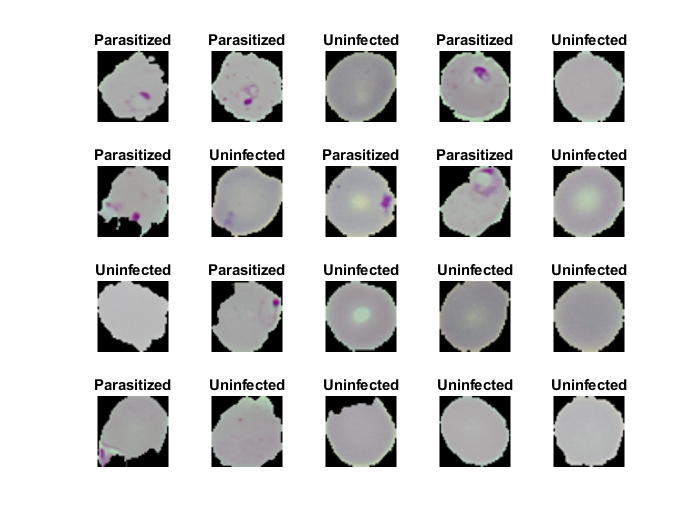

figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(reformatImage(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end

## Splitting of main data set into Training, Testing and validation

As per the instruction given for the project We are to split the given dataset into 80-20 for training and testing and 90-10 for validation

% Split the Training and Testing Dataset
train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);

## Deep CNN and Transfer Learning

The below code segment deals with the transfer learning approach for which we have taken VGG16

**The Mini Batch size is 16** - The reason for choosing such a small mini batch size is to avoid GPU out of memory error.

**Number of Epochs is 2**

The VGG 16 Architechture is altered here to accomodate 2 classes so it has only a fully connected layer of 2 units.

**I had tried increasing the number of layer but due to poor computational power i wasnt able to proceed so had to reduce.**

%Initializing architechture
net = vgg16;

%Removing the fully connected layers in the end to adapt to 2 classes
layersTransfer = net.Layers(1:end-9);


% Clear the existing alexnet architecture
clear net;

numClasses=numel(categories(imdsTrain.Labels));

% Define the new layers 

layers=[

        layersTransfer
             
        fullyConnectedLayer(2);
         
        softmaxLayer
        classificationLayer
 
  ];


imdsTrain.ReadFcn=@(filename)reformatImage(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);
imdsValid.ReadFcn=@(filename)reformatImage(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);

options=trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'MaxEpochs',2, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',imdsValid, ...
    'ValidationFrequency',100,'ValidationPatience',4, ...
    'Verbose',false, ...
    'Plots','training-progress');    

gpuDevice(1);


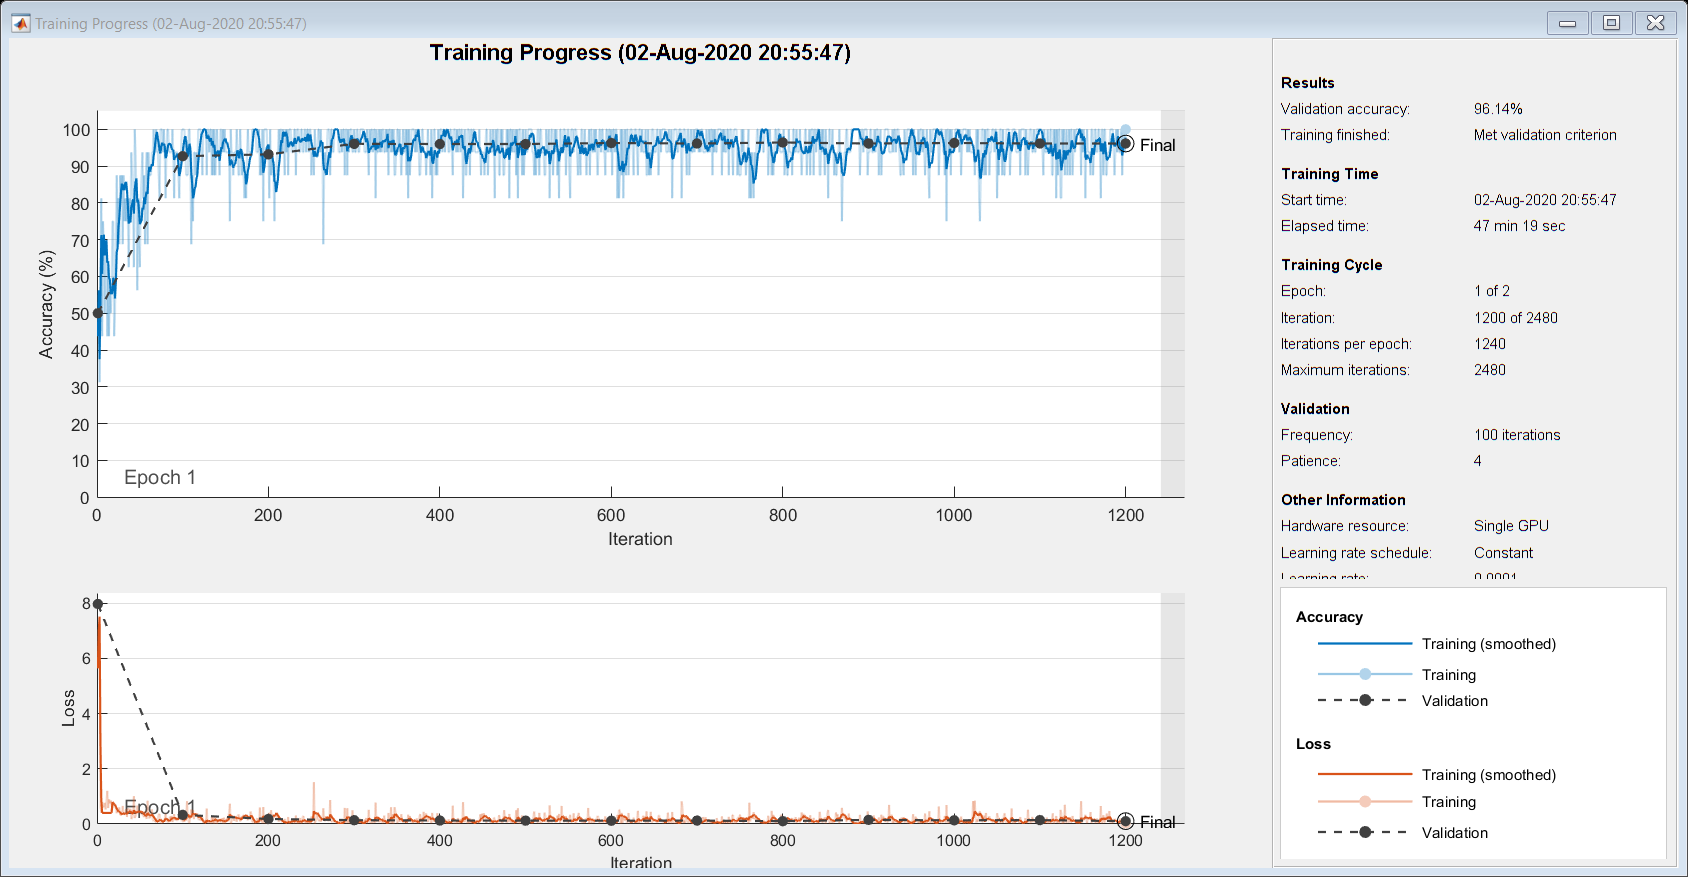

netTransfer =   SeriesNetwork with properties:

    Layers: [35×1 nnet.cnn.layer.Layer]



% Train the network
netTransfer=trainNetwork(imdsTrain,layers,options)

**Testing the Model**

I had issues with using the test data totally due to poor computational power.

**To overcome this issue, i adopted a method similar to K-fold validation.**

Since the **splitEachLabel **function is a random function, i reduced the split ratio and added the entire code to a loop.

I then combined the results of multiple loops to come up with the Confusion matrix

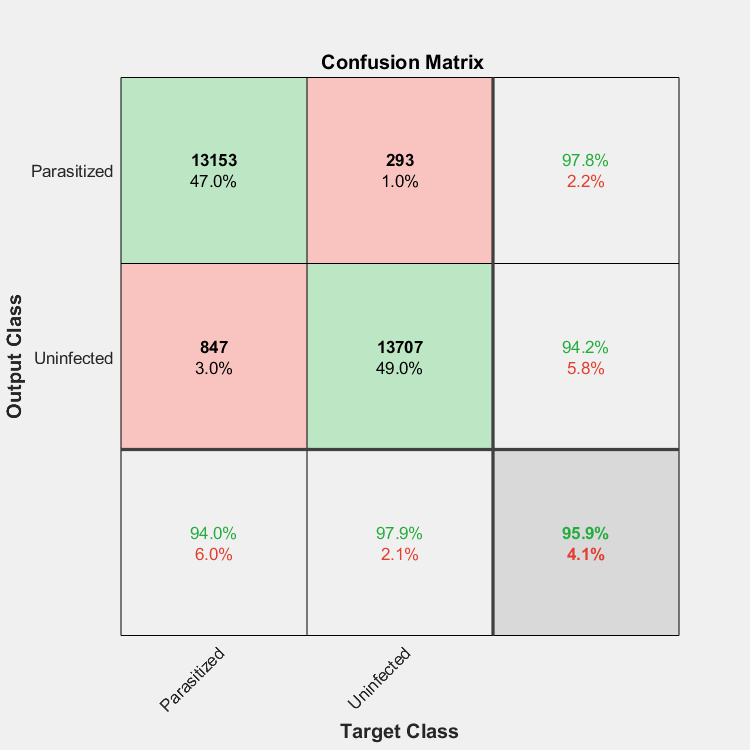

testLabs = [];
predLabs = [];
postLabs = [];


for i=1:500
    [imdsTest1,imdsTest2]=splitEachLabel(imdsTest,0.01,'randomize');
    
    imdsTest1.ReadFcn=@(filename)reformatImage(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);
    
    % Predict Test Labels using Classify command
    [predicted_labels,posterior]=classify(netTransfer,imdsTest1);
    
    
    predLabs = [predLabs;predicted_labels];
    testLabs = [testLabs;imdsTest1.Labels];
    postLabs = [postLabs;posterior];
    
end
plotconfusion(testLabs,predLabs);

## AUC - ROC Curve

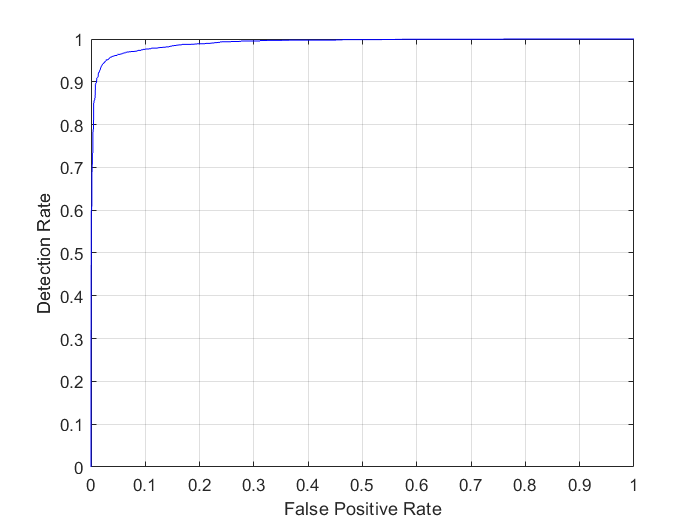

test_labels=double(nominal(testLabs));

[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,postLabs(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


AUC

AUC = 0.9910

## Pre Processing Function

The preprocessing function uses Color constancy to prepare the data set for processsing

The commented segment in the middle can be used for data augmentation which rotates images randomly

function [result] = reformatImage(filename,image_size)

    I = imread(filename);
  
        %Average of all values in an image
            rCh      = sum(sum(I(:,:,1)))/(size(I,1)*size(I,2));
            gCh      = sum(sum(I(:,:,2)))/(size(I,1)*size(I,2));
            bCh      = sum(sum(I(:,:,3)))/(size(I,1)*size(I,2));
           %Mean of all channel averages
            mN        = mean([rCh gCh bCh]);
          
            res(:,:,1) = (mN/rCh)*double(I(:,:,1));
            res(:,:,2) = (mN/gCh)*double(I(:,:,2));
            res(:,:,3) = (mN/bCh)*double(I(:,:,3));
    
%             val = randperm(4);
%             
%             if val == 1
%                 res = imrotate(res,-90);
%             elseif val == 2
%                 res = imrotate(res,-180);
%             elseif val == 3
%                 res = imrotate(res,-270) 
%             end
            
            
    res = uint8(res);
    %resize image to fit first convolution layer
    result = imresize(res,image_size); 
    
end
